clear; close all; rng(0); mpt_init;

MPT searches for solvers on the path ...
 
 LINPROG ............................................ linprog.m 
 QUADPROG .......................................... quadprog.m 
 GLPK .................................................. glpkcc 
 CDD ................................................... cddmex 
 MOSEK ............................................... mosekopt 
 LCP ...................................................... lcp 
 SEDUMI .............................................. sedumi.m 
 PLCP .............................................. mpt_plcp.m 
 MPQP .............................................. mpt_mpqp.m 
 MPLP .............................................. mpt_mplp.m 
 ENUMPLCP ..................................... mpt_enum_plcp.m 
 ENUMPQP ....................................... mpt_enum_pqp.m 
 RLENUMPQP ..................................... mpt_enum_pqp.m 

MOSEK Version 11.0.14 (Build date: 2025-4-3 22:32:03)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform:

yalmip('clear');
optm = which('optimizer');
extrasDir = fileparts(fileparts(optm));
addpath(extrasDir,'-begin');
rehash toolboxcache;

# LK dynamics

The Lane Keeping Problem refers to the task where an autonomous vehicle must stay within its designated lane, particularly when navigating curves. A classic control approach to address this problem is to design an LQR (Linear Quadratic Regulator) controller based on the linearized model of the vehicle's dynamics:


$$\left\{
\begin{array}{l}
\dot{y} = \nu + v_0 \psi,\\
\dot{\nu} = -\frac{C_f + C_r}{M v_0} \nu 
            + \left(\frac{b C_r - a C_f}{M v_0} - v_0\right) r 
            + \frac{C_f}{M} u,\\
\dot{\psi} = r,\\
\dot{r} = \frac{b C_r - a C_f}{I_z v_0} \nu
          - \frac{a^2 C_f + b^2 C_r}{I_z v_0} r
          + a \frac{C_f}{I_z} u - r_d
\end{array}
\right.
$$


[nx,nz,nu]=deal(4,1,1);

where $y
$ and $$\psi$$ are the lateral displacement and yaw angle error in road-fixed coordinates, respectively, $$\nu$$ is the lateral velocity, and $$r$$ is the yaw rate (rotation rate about the vertical axis of the road-fixed coordinates). Additionally, $$M$$ and $$I_z$$ represent the mass of the vehicle and the moment of inertia about its center of mass, respectively, while $$a$$ and $$b$$ denote the distances from the center of mass to the front and rear tires. $$C_f$$ and $$C_r$$ are the cornering stiffness coefficients of the front and rear tires, respectively. $$v_0$$ represents the constant longitudinal velocity, and $$r_d$$ is the desired yaw rate (treated as the uncontrolled input $$z_k$$). The control input $$u$$ represents the front wheel steering angle.

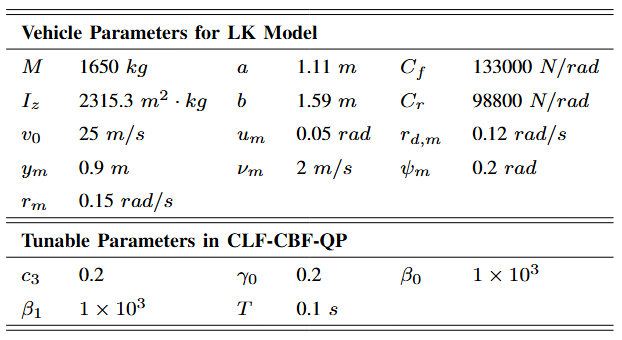

We use the parameters in the above Table for the LK simulation.

[M,Iz,a,b,Cf,Cr,v0]=deal(1650,2315.3,1.11,1.59,133000,98800,25);
[um,rdm,ym,vm,psim,rm]=deal(0.1,0.15,0.9,2.5,0.2,0.2);
[c3,gamma0,beta0,beta1,T]=deal(0.2,0.2,1e3,1e3,0.1);

A=[0,1,v0,0;
   0,-(Cf+Cr)/(M*v0),0,(b*Cr-a*Cf)/(M*v0)-v0;
   0,0,0,1;
   0,(b*Cr-a*Cf)/(Iz*v0),0,-(a^2*Cf+b^2*Cr)/(Iz*v0)];
B=[0 0;Cf/M 0;0 -1;a*Cf/Iz 0];

Define input set $\mathcal{U}\gets \mathcal P_u, \mathcal{Z}\gets \mathcal P_z$,


$$\mathcal{U} = \{u \mid -u_m \le u \le u_m\},\quad
\mathcal{Z} = \{r_d \mid -r_{d,m} \le r_d \le r_{d,m}\}.
$$


we impose conservative but realistic bounds on these states, leading to the polyhedral safety set $\mathcal{C}\gets \mathcal P_x$:


$$\mathcal{C}^b
=
\left\{
\left.
\begin{array}{c}
y\\ \nu\\ \psi\\ r
\end{array}
\right|
\begin{array}{l}
-y_m \le y \le y_m\\
-\nu_m \le \nu \le \nu_m\\
-\psi_m \le \psi \le \psi_m\\
-r_m \le r \le r_m
\end{array}
\right\}
$$


[Pu,Pxb,Pz]=deal(Polyhedron([-1;1],[um;um]),Polyhedron([eye(nx);-eye(nx)],kron([1;1],[ym;vm;psim;rm])),Polyhedron([-1;1],[rdm;rdm]));
Px=Polyhedron([1 0 0 0;-1 0 0 0],[ym;ym]);

Pu=Pu.minHRep.minVRep;
Pxb=Pxb.minHRep.minVRep;
Pz=Pz.minHRep.minVRep;

# LK Sample

Given that we use the linear LK dynamics, so we just sample 1 trajectory with $\ell=2(n_u+n_x+n_z+1)$.

ell=2*(nu+nx+nz+1);

Choose a random point in the safety set $\mathcal C\gets \mathcal P_x$:

X0=zeros(nx,ell); for i=1:ell,X0(:,i)=Pxb.randomPoint;end

with a random squence $U_0=[u_1,u_2,\ldots,u_\ell]\in \mathcal C, Z_0=[z_1,z_2,\ldots,z_\ell]\in \mathcal Z$:

U0=zeros(nu,ell); for i=1:ell,U0(:,i)=Pu.randomPoint;end
Z0=zeros(nz,ell); for i=1:ell,Z0(:,i)=Pz.randomPoint;end

## Sampling

Discretize continuous dynamics with sample time $T$

sysc = ss(A,B,[],[]);
sysd = c2d(sysc,T);          
[Ad,Bd] = ssdata(sysd);

Generate $X_0,X_1$ from one trajectory

X1=zeros(nx,ell);
for k = 1:ell
    xk = X0(:,k);
    wk = [U0(:,k); Z0(:,k)];
          
    xk_next = Ad*xk + Bd*wk; 
    X1(:,k) = xk_next;       

    xk = xk_next;          
end

## Compute Control Invariant Set

tic;Xf=AlgorithmCIS(U0,X0,Z0,X1,Pu,Pxb,Pz); toc

Iteration: 21
Polyhedron in R^4 with representations:
    H-rep (irredundant) : Inequalities  50 | Equalities   0
    V-rep (redundant)   : Vertices 188 | Rays   0
Functions : none
历时 45.399657 秒。


report = VerifyRCIS(Xf, U0, X0, Z0, X1, Pu, Pz, [], [], 1);


=== RCIS Verification Report ===
Pgx vertices: 188, Pgz vertices: 2
Total pairs: 376 | Feasible: 376 | Infeasible: 0
RCIS satisfied: true



# LK Simulation

Initialize the controllers

C=[1 0 0 0];
Ctrl_true  = ControlAlgorithm1(Xf,Pu,Px,C,U0,X0,Z0,X1,c3,gamma0,beta0,beta1,1);
Ctrl_false = ControlAlgorithm1(Xf,Pu,Px,C,U0,X0,Z0,X1,c3,gamma0,beta0,beta1,0);
mdl='LK_sim'; 

(1) Common parameters: The same for each example

baseSim = Simulink.SimulationInput(mdl);

Adopt the quadratic Lyapunov function $\(V(x) = (Cx-r)^\top (Cx-r)\) with \(P = C^\top C \succeq 0\)$.

baseSim = baseSim.setVariable('T',      T) ...
                 .setVariable('nx',     nx) ...
                 .setVariable('nu',     nu) ...
                 .setVariable('nz',     nz) ...
                 .setVariable('A',      A) ...
                 .setVariable('B',      B);

(2) To verify the CIS constraint for recursive feasibility, using all vertices of the product set$ \(\mathcal{Z} \times \mathcal{X}\)$ as initial conditions. And set flag=1/0, respectively representing whether it includes CIS constraints or not.

Xfin=Polyhedron(Xf.A,Xf.b-1e-6*ones(size(Xf.b)));

nxv = size(Xf.V,1);
nzv = size(Pz.V,1);
N   = nxv*nzv;

### With CIS

simIn(1:N,1) = baseSim; 

assignin('base','Ctrl',Ctrl_true);
for j = 1:nzv
    for i = 1:nxv
        simIn((j-1)*nxv+i) = simIn((j-1)*nxv+i).setVariable('x0',Xf.V(i,:)').setVariable('zk',Pz.V(j,:)');
    end
end

tic
simOut1 = parsim(simIn,'ShowProgress','on','UseFastRestart','on','TransferBaseWorkspaceVariables','on');

[17-Dec-2025 11:56:36] 正在检查并行池的可用性...
[17-Dec-2025 11:56:36] 正在并行工作进程上启动 Simulink...
[17-Dec-2025 11:56:37] 正在并行编译模型引用...
[17-Dec-2025 11:56:37] 正在并行工作进程上配置仿真缓存文件夹...
[17-Dec-2025 11:56:37] 正在将模型中使用的基础工作区变量传输给并行工作进程...
[17-Dec-2025 11:56:37] 要发送到并行工作进程的基础工作区变量的总大小为 3.12 MB。
[17-Dec-2025 11:56:38] 正在并行工作进程上加载模型...
[17-Dec-2025 11:56:42] 正在运行仿真...
[17-Dec-2025 11:56:51] 已完成 1 次仿真运行，共 376 次
[17-Dec-2025 11:56:51] 从并行工作进程接收的运行 1 的仿真输出(大小: 14.37 KB)。
[17-Dec-2025 11:56:51] 已完成 2 次仿真运行，共 376 次
[17-Dec-2025 11:56:51] 从并行工作进程接收的运行 2 的仿真输出(大小: 14.36 KB)。
[17-Dec-2025 11:56:51] 已完成 3 次仿真运行，共 376 次
[17-Dec-2025 11:56:51] 从并行工作进程接收的运行 3 的仿真输出(大小: 14.36 KB)。
[17-Dec-2025 11:56:51] 已完成 4 次仿真运行，共 376 次
[17-Dec-2025 11:56:51] 从并行工作进程接收的运行 4 的仿真输出(大小: 14.37 KB)。
[17-Dec-2025 11:56:51] 已完成 5 次仿真运行，共 376 次
[17-Dec-2025 11:56:51] 从并行工作进程接收的运行 5 的仿真输出(大小: 14.37 KB)。
[17-Dec-2025 11:56:51] 已完成 6 次仿真运行，共 376 次
[17-Dec-2025 11:56:51] 从并行工作进程接收的运行 6 的仿真输出(大小: 14.42 KB)。
[17-Dec-2025 11:56:51] 已完成 7 次仿真运行，共 376

toc

历时 52.915856 秒。


### Without CIS

simIn(1:N,1) = baseSim; 

assignin('base','Ctrl',Ctrl_false);
for j = 1:nzv
    for i = 1:nxv
        simIn((j-1)*nxv+i) = simIn((j-1)*nxv+i).setVariable('x0',Xf.V(i,:)').setVariable('zk',Pz.V(j,:)');
    end
end

tic
simOut0 = parsim(simIn,'ShowProgress','on','UseFastRestart','on','TransferBaseWorkspaceVariables','on');

[17-Dec-2025 11:57:29] 正在检查并行池的可用性...
[17-Dec-2025 11:57:29] 正在并行工作进程上启动 Simulink...
[17-Dec-2025 11:57:29] 正在并行编译模型引用...
[17-Dec-2025 11:57:29] 正在并行工作进程上配置仿真缓存文件夹...
[17-Dec-2025 11:57:29] 正在将模型中使用的基础工作区变量传输给并行工作进程...
[17-Dec-2025 11:57:29] 要发送到并行工作进程的基础工作区变量的总大小为 8.48 MB。
[17-Dec-2025 11:57:30] 正在并行工作进程上加载模型...
[17-Dec-2025 11:57:31] 正在运行仿真...
[17-Dec-2025 11:57:33] 已完成 1 次仿真运行，共 376 次
[17-Dec-2025 11:57:33] 从并行工作进程接收的运行 1 的仿真输出(大小: 14.58 KB)。
[17-Dec-2025 11:57:33] 已完成 2 次仿真运行，共 376 次
[17-Dec-2025 11:57:33] 从并行工作进程接收的运行 2 的仿真输出(大小: 14.60 KB)。
[17-Dec-2025 11:57:33] 已完成 3 次仿真运行，共 376 次
[17-Dec-2025 11:57:33] 从并行工作进程接收的运行 3 的仿真输出(大小: 14.60 KB)。
[17-Dec-2025 11:57:33] 已完成 4 次仿真运行，共 376 次
[17-Dec-2025 11:57:33] 从并行工作进程接收的运行 4 的仿真输出(大小: 14.60 KB)。
[17-Dec-2025 11:57:33] 已完成 5 次仿真运行，共 376 次
[17-Dec-2025 11:57:33] 从并行工作进程接收的运行 5 的仿真输出(大小: 14.59 KB)。
[17-Dec-2025 11:57:33] 已完成 6 次仿真运行，共 376 次
[17-Dec-2025 11:57:33] 从并行工作进程接收的运行 6 的仿真输出(大小: 14.66 KB)。
[17-Dec-2025 11:57:33] 已完成 7 次仿真运行，共 376

toc

历时 43.699461 秒。


load('EnvirInfo.mat');display(report);

report =     'Environment (reproducibility).
       OS: Windows Microsoft Windows 11 专业版
       CPU: 12th Gen Intel(R) Core(TM) i7-12700KF (12 cores)
       MATLAB: MATLAB 25.1.0.2973910 (R2025a) Update 1 (R2025a, Update 1)
       Solvers/Libraries: MOSEK: MOSEK Version 11.0.14 (Build date: 2025-4-3 22:32:03); YALMIP: 20250626; MPT3: 3.2.1
       MATLAB toolboxes (required by LK_demo + LK_sim): Control System Toolbox, Simulink
       MATLAB toolboxes (required by ACC_demo + ACC_Sample + ACC_sim): Automated Driving Toolbox, Simulink
     '


# Visualisation

With CIS:    N=30080, mean=8.177 ms, median=7.779 ms, p95=10.255 ms
Without CIS: N=30080, mean=8.624 ms, median=6.892 ms, p95=19.620 ms


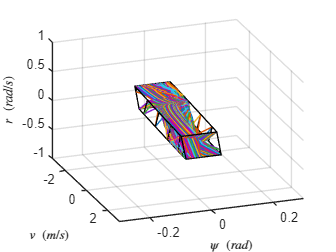

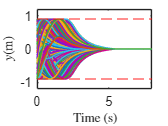

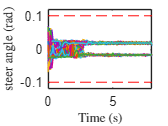

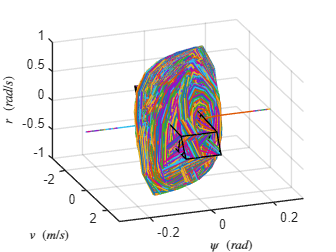

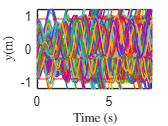

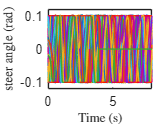

run('LK_draw');